# עבודת בית מספר 2 - תאריך הגשה .31.12.2020

# SCE Digital Image Processing 3 - 20.12.2020

# Benny Aman 205873599

# Sapir Seluk 308308980

## עד מתי להגיש את העבודה :

 You have to post it to the Moodle Box which is going to be opened in the Moodle Adress of the Course before 31.12.2020.

Enjoy your work

## How to send your work 

- Submit your work in the Moodle Assignment Box : Assignment 2 _2020_DigitalImageProcessing in the Moodle site of the Course.

- This is an open-book Assignment, which means you may consult lecture notes, internet resources and other ressources. 

- You can do the Assignment by 2 (and no more please) , but do not share your Assignment to other groups. Indeed, Copy/Paste of entire answer from internet is **not permitted**. *Please give answers in your own words.*

- This Assignment will take you an estimated time of 4.0 hours

## Next bohan

- the bohan is reported to December 3th, 2020 - program will be given latter.

## Aim of the Assignment

This assignment comprised two parts:

### Part 1: **Morphological Image Processing**

- Remove the noise from the input image Q4_1.tif. Submit your code and the output image.

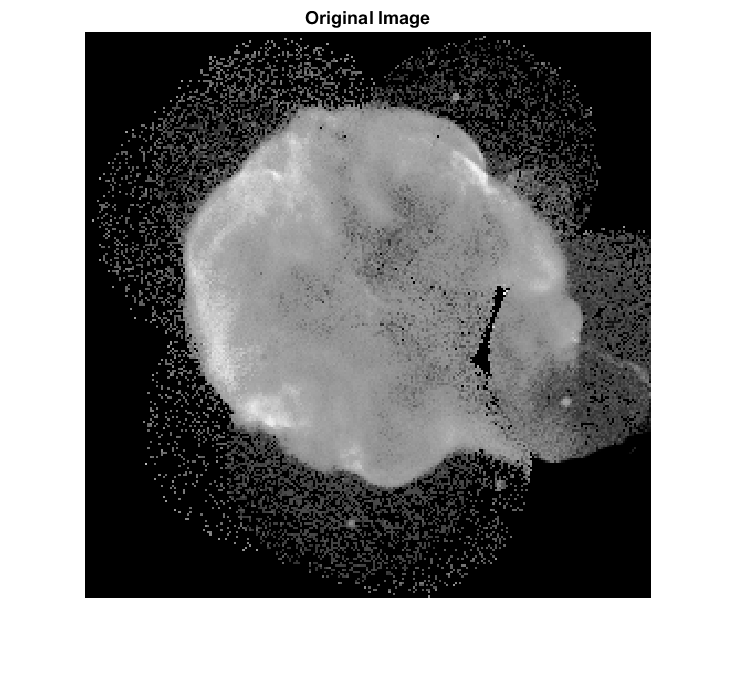

clc
clear all
close all

a = imread('Q4_1.tif');
figure,imshow(a),title('Original Image');

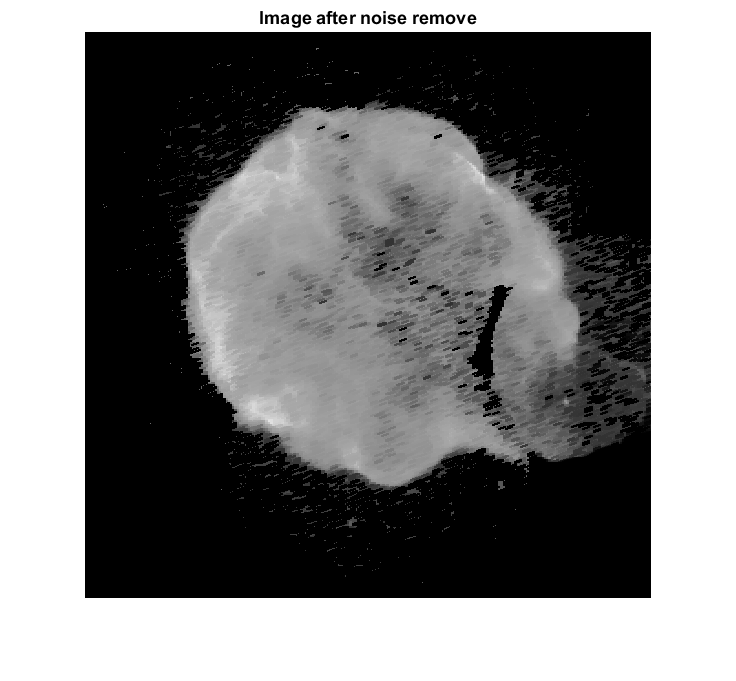


se = strel('line',7,12);
erodedBW = imerode(a,se);
figure,imshow(erodedBW),title('Image after noise remove')

#### Part 2:  Gradients details 

- Extract the gradient parts from the input input Q4_2.tif.

לפי קאני

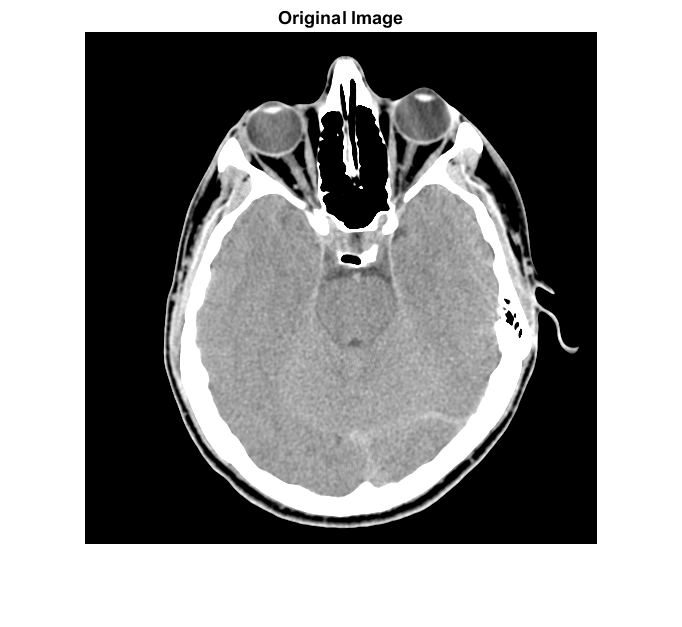

b = imread("Q4_2.tif");
figure,imshow(b),title('Original Image');

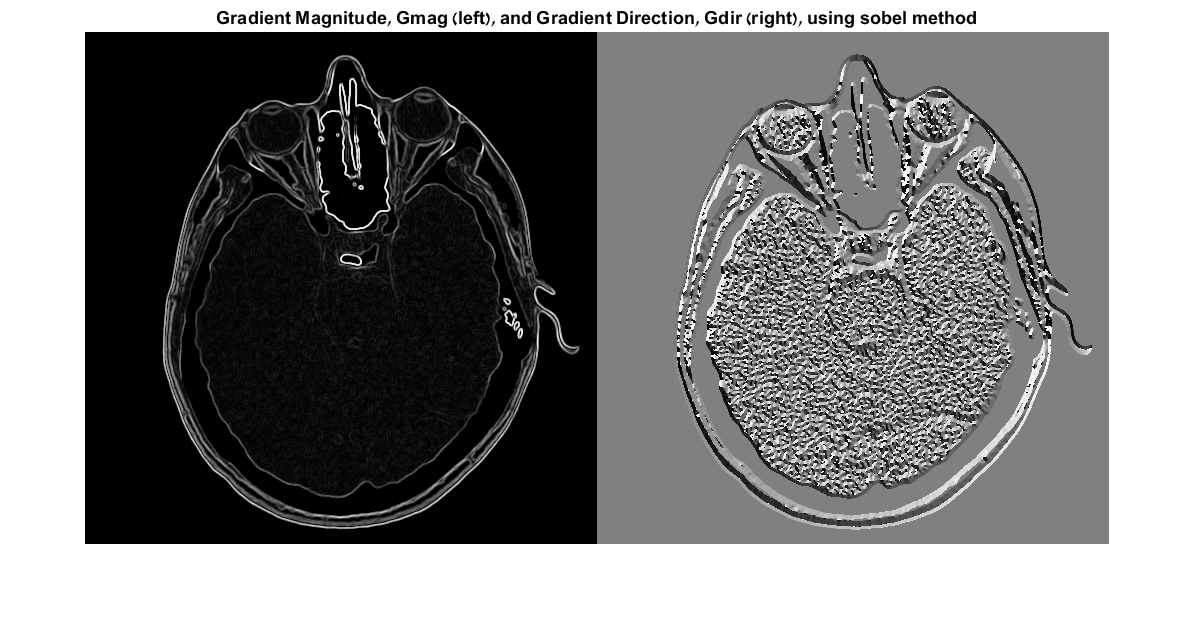

[Gmag, Gdir] = imgradient(b,'sobel');
figure
imshowpair(Gmag, Gdir, 'montage');
title('Gradient Magnitude, Gmag (left), and Gradient Direction, Gdir (right), using sobel method')

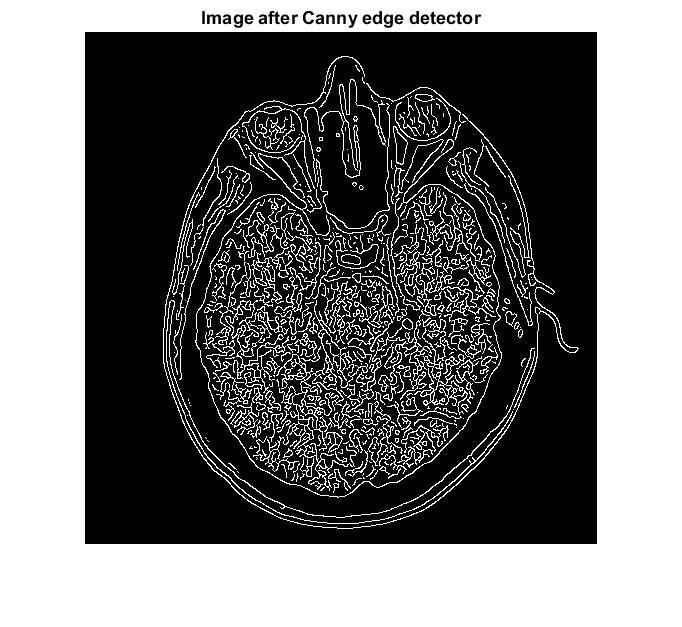


BW = edge(b,'Canny');
figure,imshow(BW),title('Image after Canny edge detector')

#### Part 3: Extraction of shape in a image of same size

- Extract the rice objects from the input Q4_3.tif

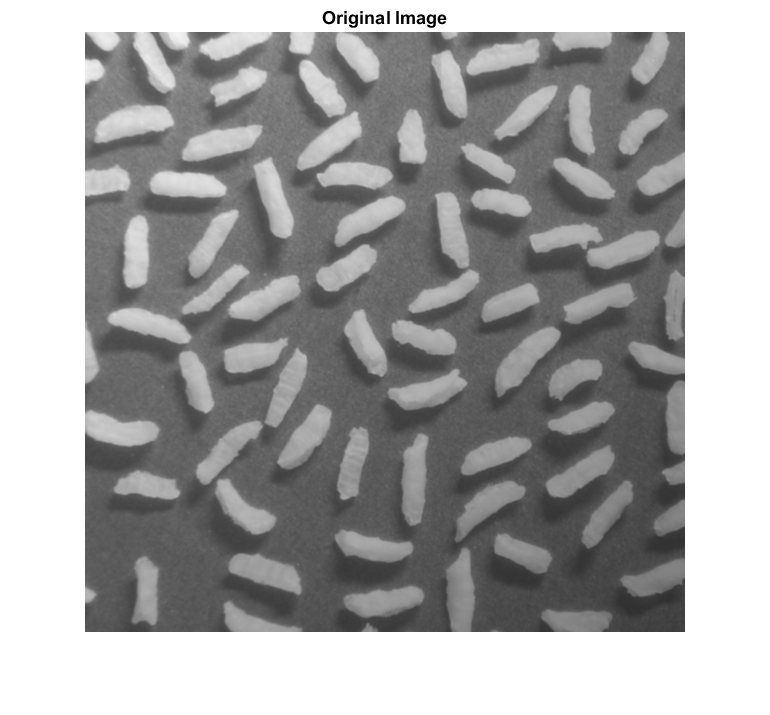

c = imread("Q4_3.tif");
figure,imshow(c),title('Original Image');

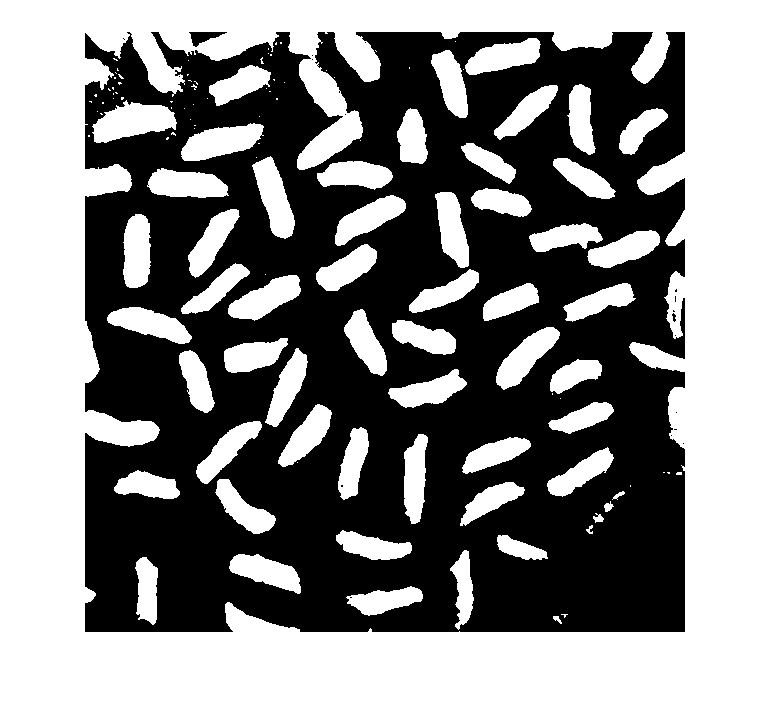

% Pick a disk that will just fit inside the pennies
SE = strel('disk', 6, 0); % 
C2 = imopen(c,SE); figure, imshow(C2,[]);
% Threshold to get the pennies B = Iopen > 150;
B = im2bw(c,graythresh(c));
figure, imshow(B);

L = bwlabel(B); % זיהוי האובייקטים
props = regionprops(L)

props = 144×1 struct array with fields:
    Area
    Centroid
    BoundingBox


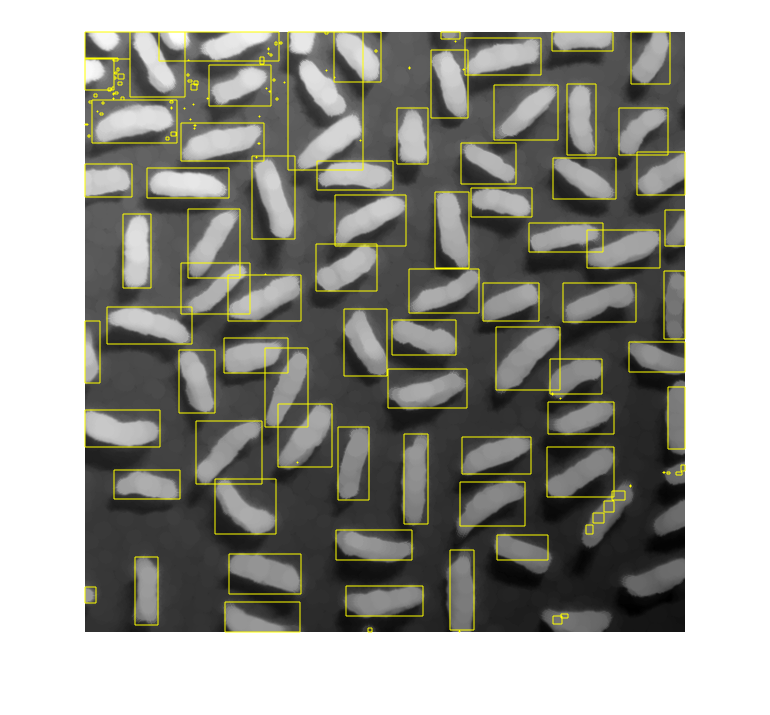

figure(7);
for i=1:length(props)
 rectangle('Position', props(i).BoundingBox, 'EdgeColor', 'y'); 
end

disp(props)

  144×1 struct array with fields:

    Area
    Centroid
    BoundingBox



#### Part 4: Multi-scaling recognition

- Seperate the two types of blobs in the input Q4_4.tif

grayImage = imread("Q4_4.tif");

% Get the dimensions of the image.
% numberOfColorChannels should be = 1 for a gray scale image, and 3 for an RGB color image.
[rows, columns, numberOfColorChannels] = size(grayImage)

rows = 600

columns = 600

numberOfColorChannels = 1

if numberOfColorChannels > 1
	% It's not really gray scale like we expected - it's color.
	% Use weighted sum of ALL channels to create a gray scale image.
	grayImage = rgb2gray(grayImage);
end
% Display the image.
subplot(2, 3, 1);
imshow(grayImage);
axis('on', 'image');
title('Original Grayscale Image');
impixelinfo;
hFig = gcf;
hFig.WindowState = 'maximized'; 
drawnow;

% Binarize the image.
binaryImage = ~imbinarize(grayImage);
% Get rid of particles less than 200 in area.
binaryImage = bwareaopen(binaryImage, 200);
% Eliminate partial blobs - those touching the edge of the image.
binaryImage = imclearborder(binaryImage);
subplot(2, 3, 2);
imshow(binaryImage, []);
axis('on', 'image');
title('Mask Image');
impixelinfo;
drawnow;

% Find blobs
props = regionprops(binaryImage, 'Centroid', 'Area');
xy = vertcat(props.Centroid)

xy =    23.9588  250.9849
   42.0399  528.0530
   49.0371  339.0302
   56.0440  119.9855
   62.9657  209.0596
   65.0179  478.0165
   87.0398   32.0247
   92.0603  267.0480
  101.9144  410.0836
  113.0454  170.0165


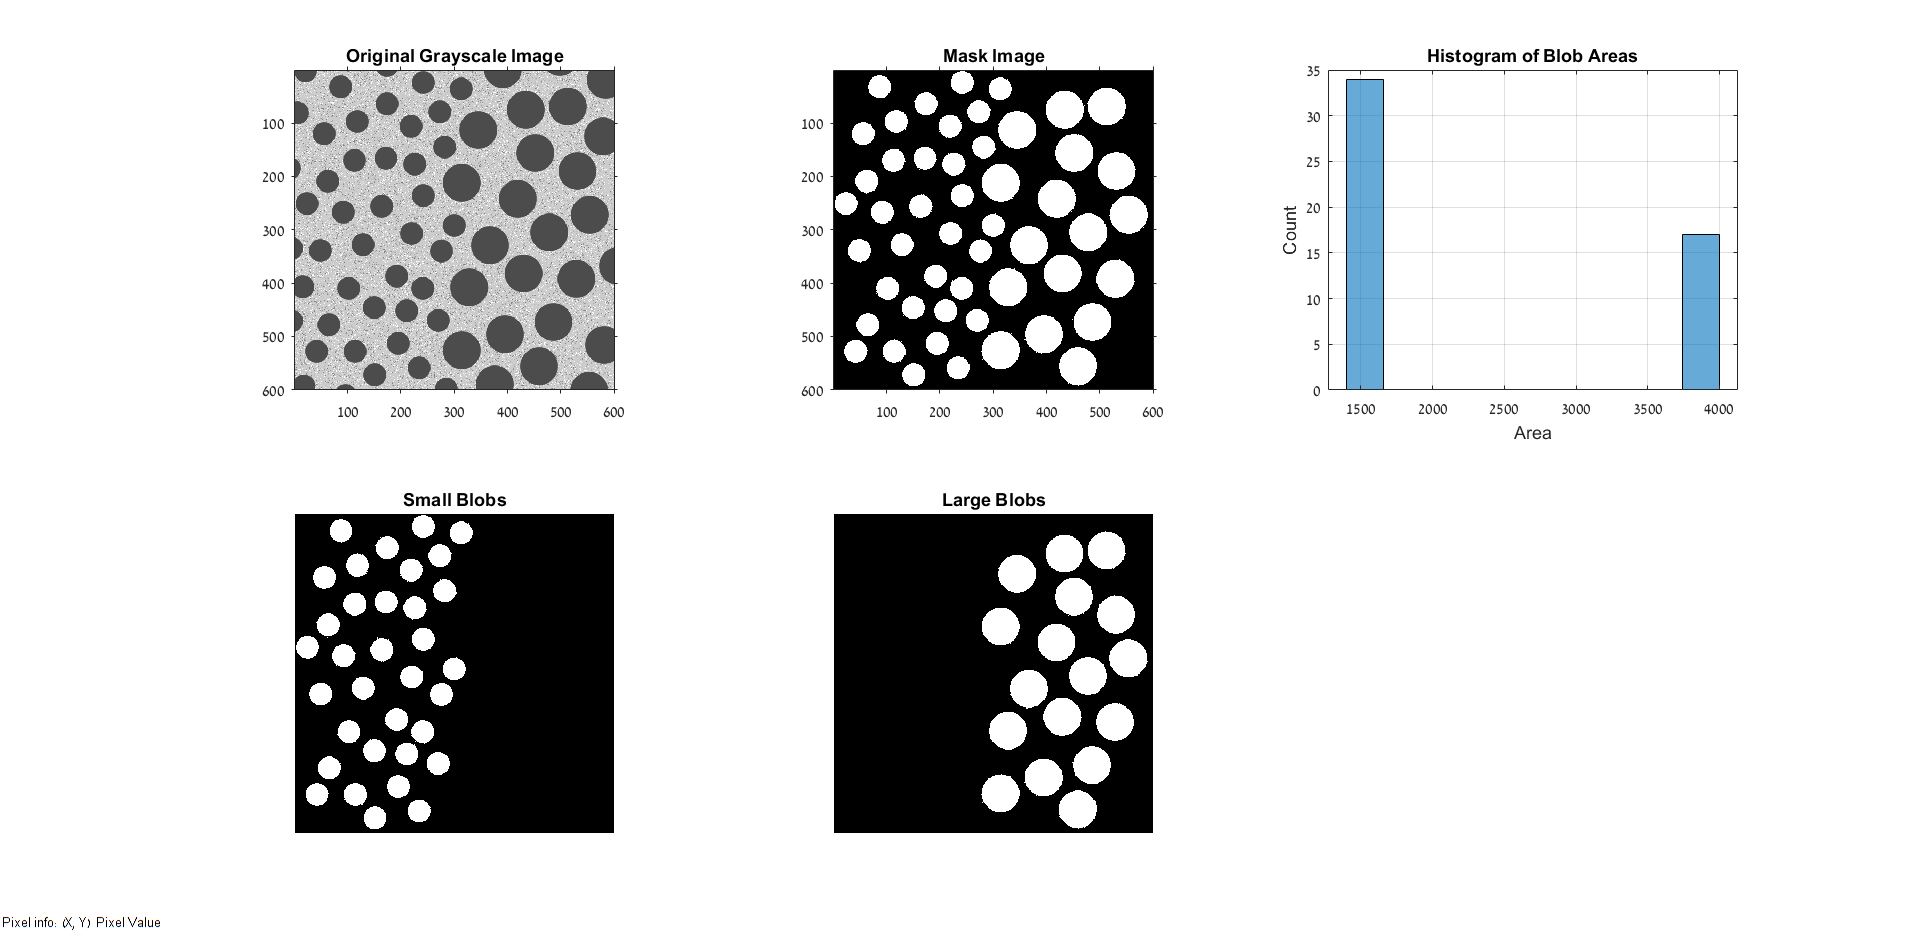

allAreas = [props.Area];
subplot(2, 3, 3);
histogram(allAreas, 10);
grid on;
title('Histogram of Blob Areas');
xlabel('Area');
ylabel('Count');

% Get blobs smaller than 2500
[labeledImage, numBlobs] = bwlabel(binaryImage);
smallIndexes = find(allAreas < 2500);
largeIndexes = find(allAreas >= 2500);
% Extract the small blobs with ismember()
smallBlobs = ismember(labeledImage, smallIndexes);
subplot(2, 3, 4);
imshow(smallBlobs);
title('Small Blobs');
% Extract the large blobs with ismember()
largeBlobs = ismember(labeledImage, largeIndexes);
subplot(2, 3, 5);
imshow(largeBlobs);
title('Large Blobs');

### How to write your project:						

- Your report should contain a brief overview of the problem, the details of your approach, and the results of your algorithm 

- Show the results of all of the main steps

- You can submit your report using the live script or create a folder with the different code and a report in word/latex file in : Assignment 3 _2020_DigitalImageProcessing in the Moodle site of the Course.		

אופציה ב

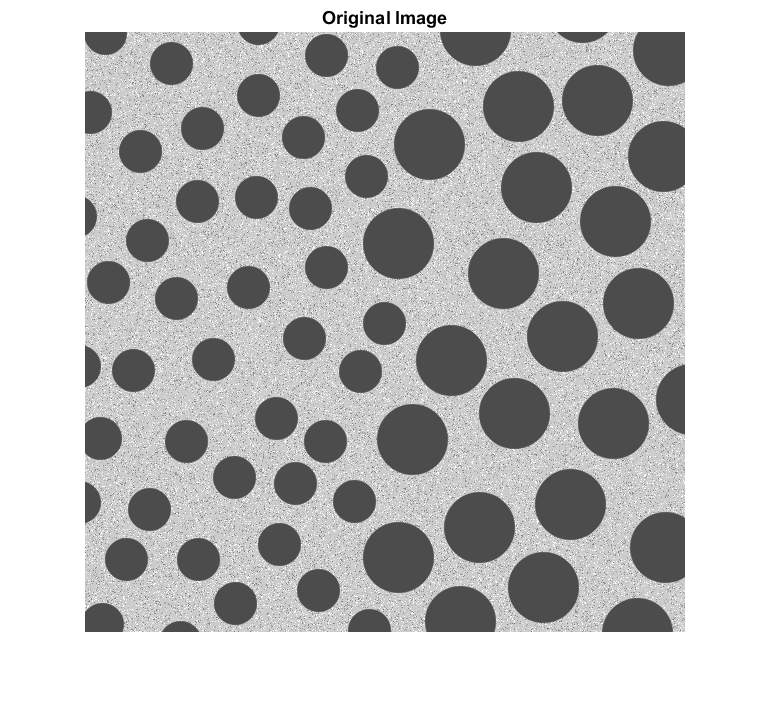

d = imread("Q4_4.tif");
figure,imshow(d),title('Original Image');

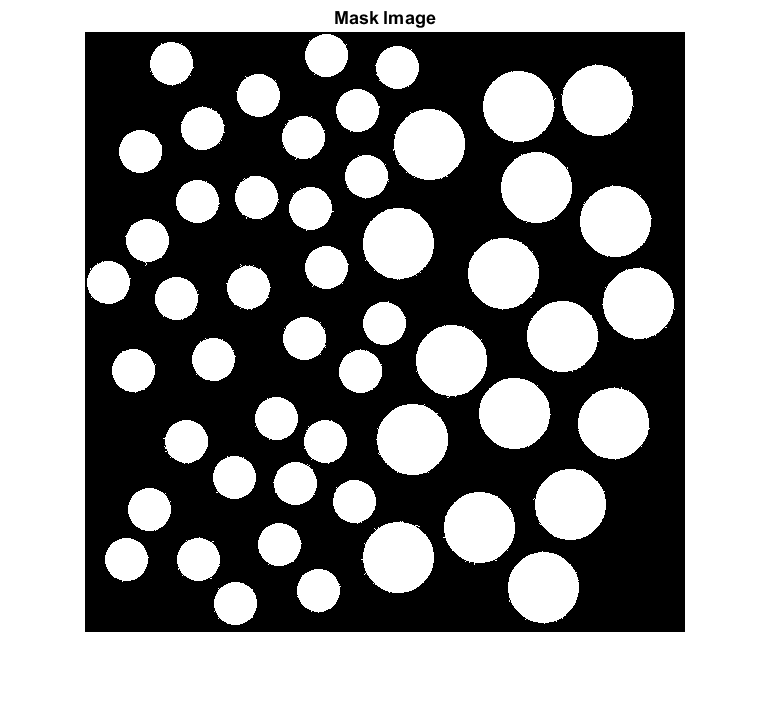


% Binarize the Image
binaryImage = im2bw(d, graythresh(d)); % הפיכת התמונה לבינארית
% Complement image 
binaryImage = ~binaryImage;

% Get rid of particles less than 200 in area.
binaryImage = bwareaopen(binaryImage, 200);
% Eliminate partial blobs - those touching the edge of the image.
binaryImage = imclearborder(binaryImage);

figure,imshow(binaryImage),title('Mask Image');


props = regionprops(binaryImage, 'Centroid', 'Area');
xy = vertcat(props.Centroid)

xy =    23.9588  250.9849
   42.0399  528.0530
   49.0371  339.0302
   56.0440  119.9855
   62.9657  209.0596
   65.0179  478.0165
   87.0398   32.0247
   92.0603  267.0480
  101.9144  410.0836
  113.0454  170.0165


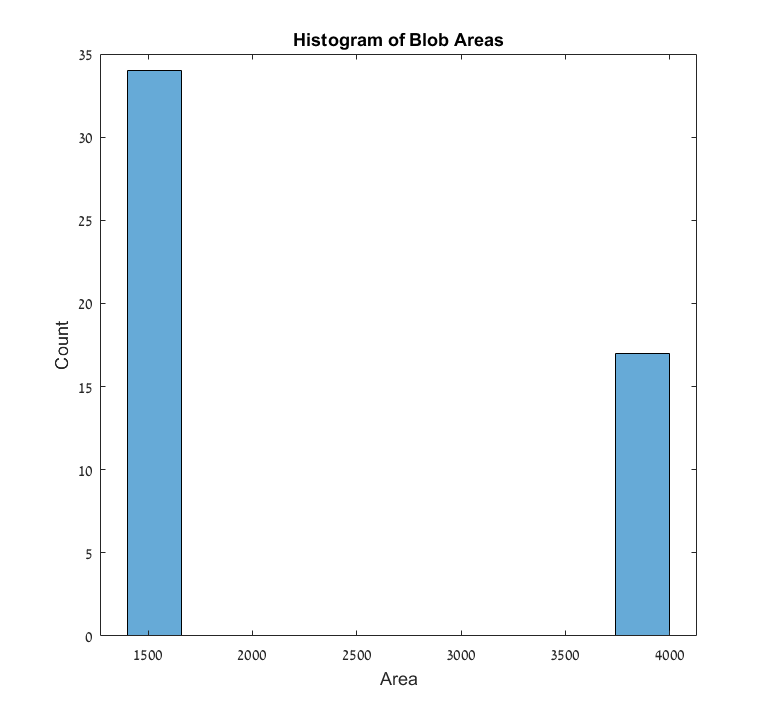

allAreas = [props.Area];
h = histogram(allAreas, 10);
title('Histogram of Blob Areas');
xlabel('Area');
ylabel('Count');

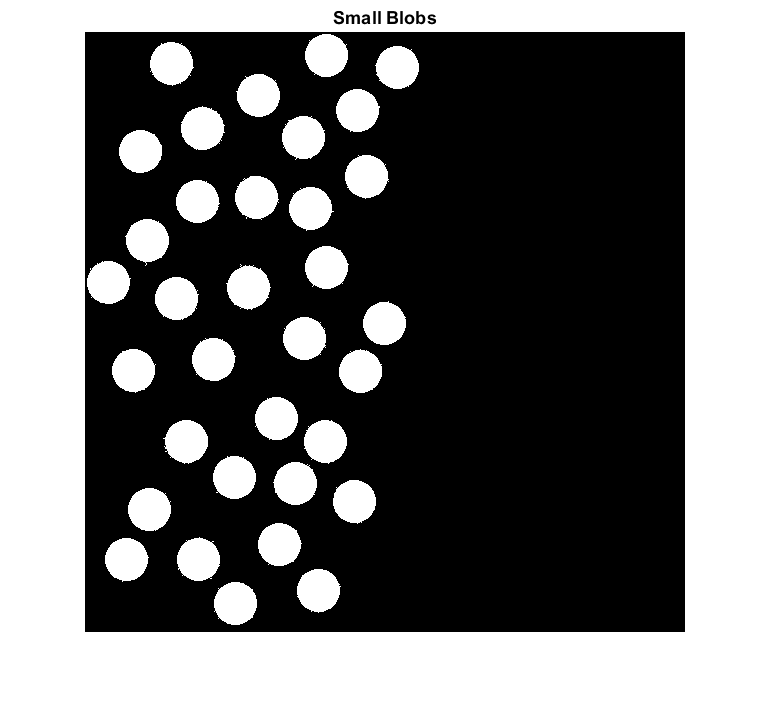


% Get blobs smaller than 2500
[labeledImage, numBlobs] = bwlabel(binaryImage);
smallIndexes = find(allAreas < 2500);
largeIndexes = find(allAreas >= 2500);
% Extract the small blobs with ismember()
smallBlobs = ismember(labeledImage, smallIndexes);
figure,imshow(smallBlobs),title('Small Blobs')

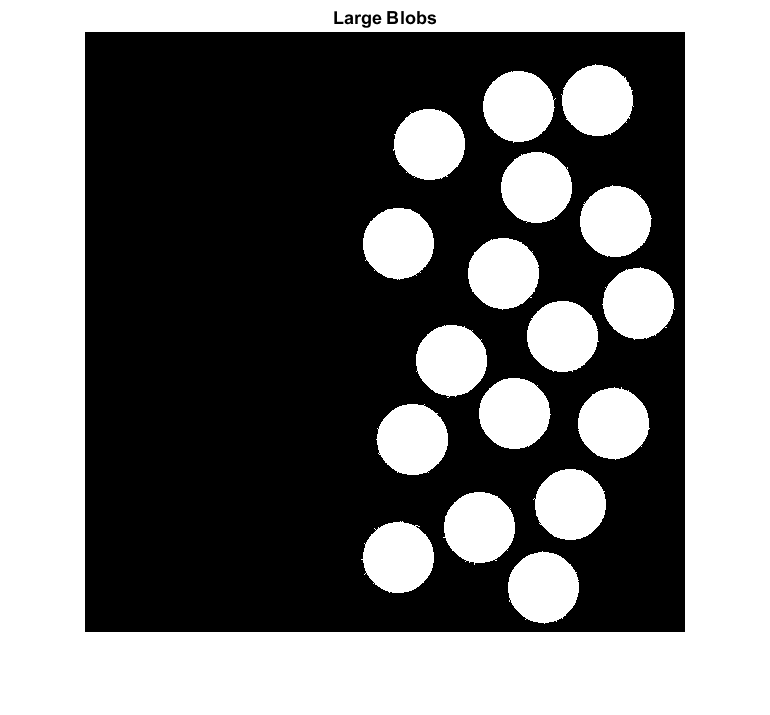


% Extract the large blobs with ismember()
largeBlobs = ismember(labeledImage, largeIndexes);
figure,imshow(largeBlobs),title('Large Blobs')